#      EXERCISE C1

     LEARNING OUTCOME:

      -   how to create time vector (span several symbol times)

      -   How to create a pulse at a given sampling rate

      -   How to perform a DFT on a given pulse

      -   How to use interpolation to reconstruct a pulse

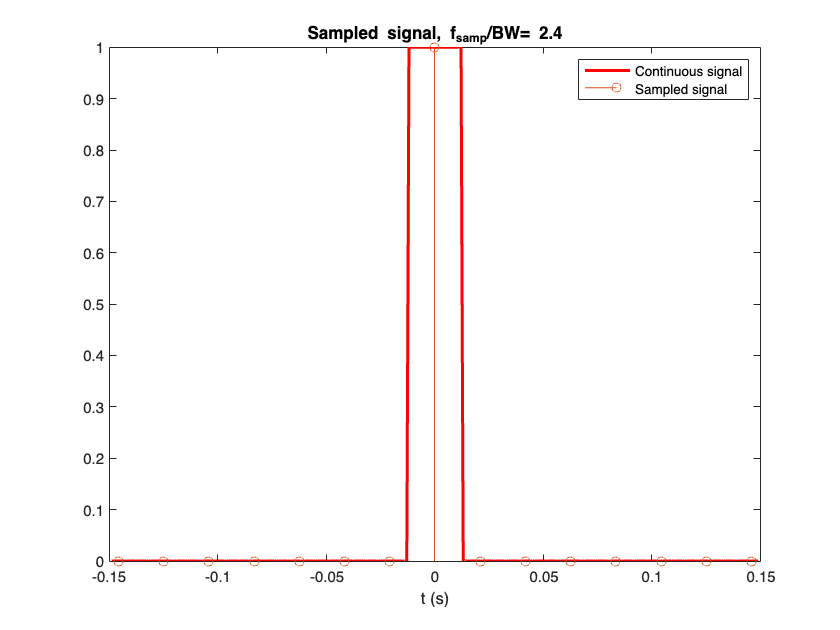

% close all
clc
clear all

% Here I have 6 different pulses you can try. Note:
%   Exercise 1 use func1
%   Exercise 2 use func2
%   Exercise 3 use func3
% Note: to create the pulses, I use anonymous functions but one can also generate the
% pulses as we did in class. This is a little bit cleaner though.
funflag = 2; %set this flag to select which pulse (1,2,3,4,5,6)

% Bandlimited signals made of sinc
func1 = @(Ts,tvec) 6*sinc(tvec/(2*Ts)).^2 + sinc(tvec/(6*Ts)).^6 + 6*sinc(tvec/(10*Ts)).^10; % This is the function in exercise 1
% Rectangular pulse
func2 = @(tau,tvec) heaviside(tau/2 + tvec) - heaviside(tvec  - tau/2); %This is the function of exercise 2
% Raised Cosine
func3 = @(alpha,tau,tvec) sinc(tvec/tau).*cos((pi*alpha/tau)*tvec)./(1-((2*alpha/tau)*tvec).^2); %This is the function in exercise 3
% Gaussian
func4 = @(sigma,tvec) exp(-tvec.^2/(2*sigma^2))/(sigma*sqrt(2*pi));
% Twosided exponential
func5 = @(a,tvec) exp(-a*abs(tvec));
% Sum of sinusoids
func6 = @(f1,f2,f3,f4,tvec) sin(2*pi*f1.*tvec) + (1/3)*sin(2*pi*f2.*tvec) + (1/5)*sin(2*pi*f3.*tvec) + (1/7)*sin(2*pi*f4.*tvec);

%% Sampling and reconstruction, RC pulse
if funflag == 3 %if we use raised cosine, we need to take alpha into account
    T_symb = 0.01;                      % Symbol time [s]
    alpha = 0.3;                    % Excess bandwidth factor
    BW = (1+alpha)/(2*T_symb);          % Occupied bandwidth (one-sided)
else
    T_symb = 0.025;                     % Symbol time [s]
    BW = 1/(2*T_symb);                  % Bandwidth (one-sided)
end

f_samp = 2.4*BW; %sampling frequency
span = 6;                           % span of time vector

tvec = eps:(1/f_samp):span*T_symb;  % create time vector (positive times)
tvec = [-fliplr(tvec(2:end)) tvec]; % Make symmetric around zero
% tvec = -span*T_symb:(1/f_samp):span*T_symb;



% Similar looking to continuous-time signal
fss = 50*BW;                                % high sampling rate
cont_tvec = eps:(1/fss):span*T_symb;                % create time vector for sampling rate
cont_tvec = [-fliplr(cont_tvec(2:end)) cont_tvec];      % Make symmetric around zero

switch funflag
    
    case 1
        fun = func1;                         % assign function handle
        p_samp = fun(T_symb,tvec);                  % create sampled signal
        p_continuous = fun(T_symb,cont_tvec);        % create "continuous" signal
        
    case 2
        fun = func2;                            % assign function handle
        p_samp = fun(T_symb,tvec);                     % create sampled signal
        p_continuous = fun(T_symb,cont_tvec);           % create "continuous" signal
        
    case 3
        fun = func3;                         % assign function handle
        p_samp = fun(alpha,T_symb,tvec);            % create sampled signal
        p_continuous = fun(alpha,T_symb,cont_tvec);  % create "continuous" signal
        
    case 4
        sigma = 1;                              % Standard deviation of pulse
        fun = func4;                            % assign function handle
        p_samp = fun(sigma,tvec);                  % create sampled signal
        p_continuous = fun(sigma,cont_tvec);        % create "continuous" signal
        
    case 5
        a = 2;                              % damping
        fun = func5;                        % assign function handle
        p_samp = fun(a,tvec);                  % create sampled signal
        p_continuous = fun(a,cont_tvec);        % create "continuous" signal
        
    case 6
        f1 = 1e3; f2= 2e3; f3 = 3e3; f4 = 4e3;  % frequencies of sinusoids
        fun = func6;                            % assign function handle
        p_samp = fun(f1,f2,f3,f4,tvec);            % create sampled signal
        p_continuous = fun(f1,f2,f3,f4,cont_tvec);  % create "continuous" signal
        
    otherwise
        return;
end


%-----------------------------------------
%       Plot Sampled and Continuous Signal
%-----------------------------------------
%SAMPLED AND TIME-CONTINUOUS SIGNAL
figure; 
plot(cont_tvec,p_continuous,'r','LineWidth',2);
hold on;
stem(tvec,p_samp); 
xlabel('t (s)')
legend('Continuous signal','Sampled signal')
title(['Sampled signal, f_{samp}/BW= ', num2str(f_samp/BW)])

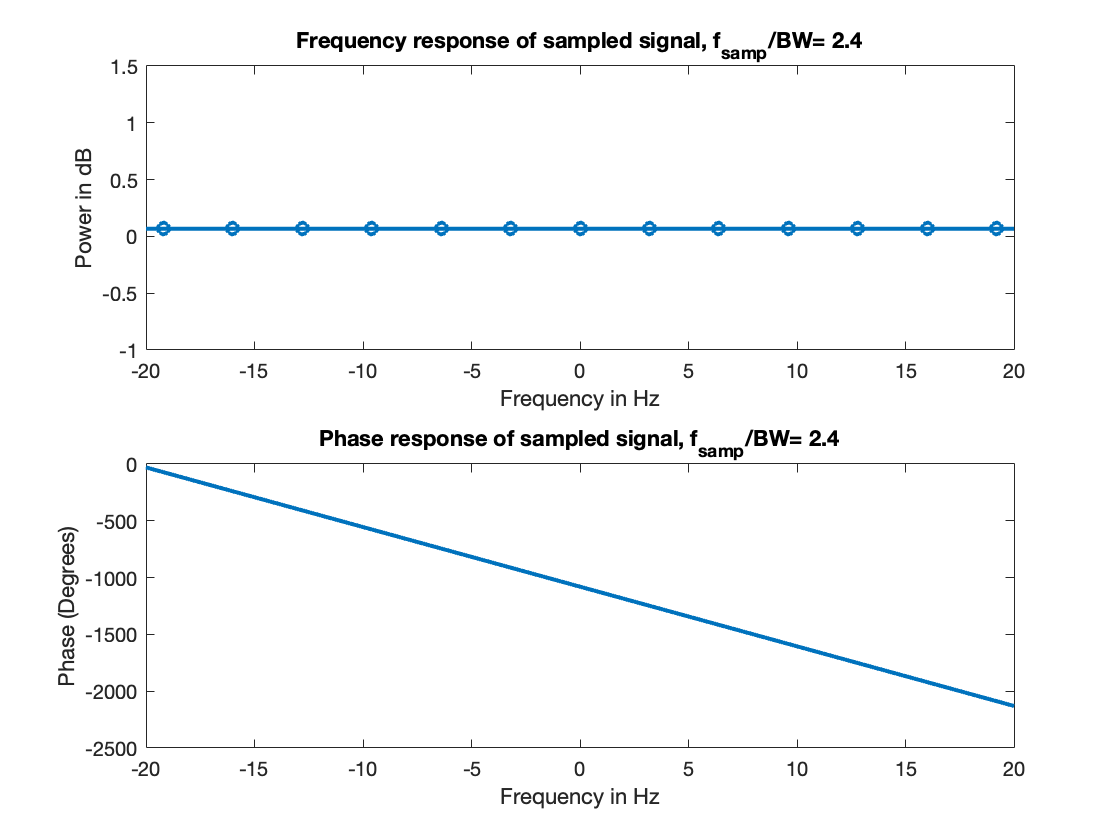


% 
% % Perform DFT and convert the digital frequencies to corresponding analog
N = length(p_samp);            % get length of signal
P = fftshift(fft(p_samp));     % Compute the Fourier transform of signal and center around zero
phase = unwrap(angle(P));   % compute phase
df = f_samp/N;                  % sampling frequency is split into N bins
fvec = df*(-floor(N/2):1:ceil(N/2)-1); % Truncated, has wide bandwidth
% %---------------------------------
% %       Plot DFT
% %---------------------------------
% % FFT PLOT
figure;
subplot(2,1,1);plot(fvec, abs(P)/N,'-o','LineWidth',2);
title(['Frequency response of sampled signal, f_{samp}/BW= ',num2str(f_samp/BW)])
xlabel('Frequency in Hz')
ylabel('Power in dB')
xlim([-1*BW,1*BW])
subplot(2,1,2); plot(fvec, phase*180/pi,'LineWidth',2)
title(['Phase response of sampled signal, f_{samp}/BW= ',num2str(f_samp/BW)])
xlabel('Frequency in Hz')
ylabel('Phase (Degrees)')
xlim([-1*BW,1*BW])

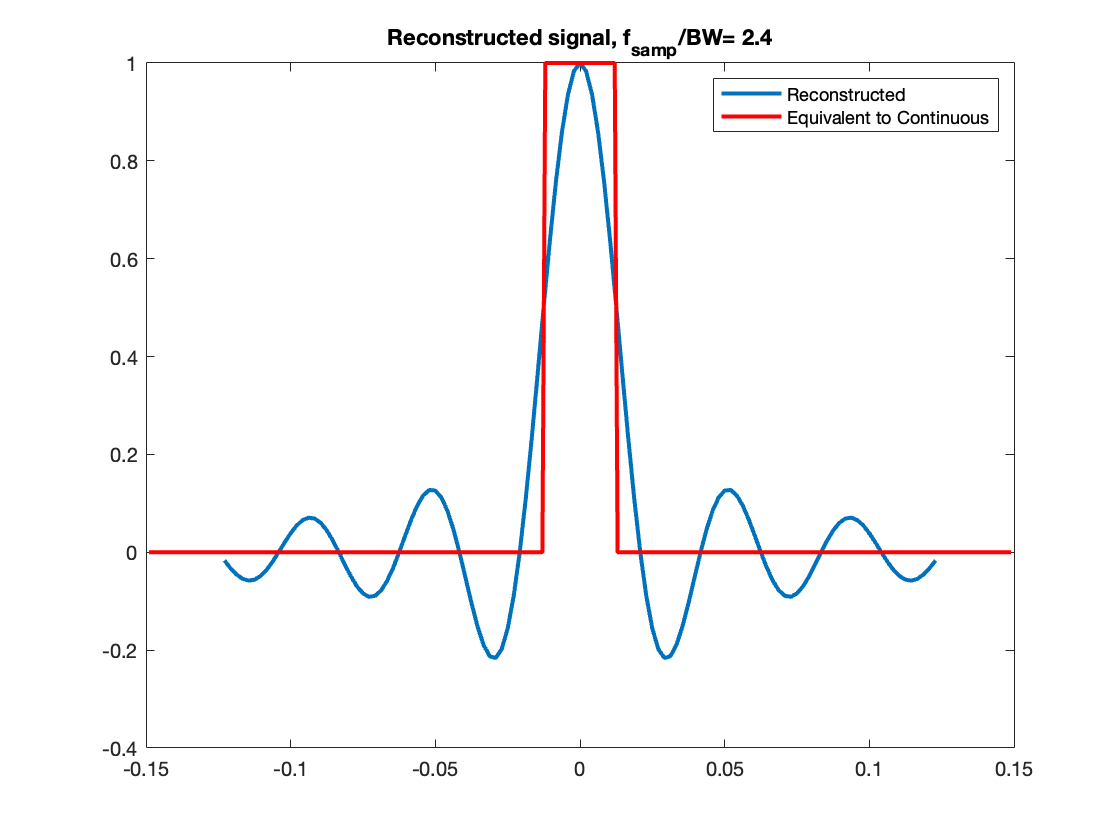


%PICK WHICH WAY YOU WANT TO RECONSTRUCT THE SIGNAL (CONVOLUTION OR FOR LOOP)
constructionFlag = 1;
if(constructionFlag==0)
    [p_recons,t_recons]= reconstruct_sinc(p_samp,f_samp,T_symb);       % Reconstruction using convolution
else
    [p_recons,t_recons]= reconstruct_sinc_forloop(p_samp,f_samp,T_symb);     % Reconstruction using for loop
end
%---------------------------------
%       Plot Reconstructed signal
%---------------------------------
% RECONSTRUCTED AND TIME-CONTINUOUS SIGNAL
figure; plot(t_recons, p_recons,'LineWidth',2); hold on;
plot(cont_tvec,p_continuous,'r','LineWidth',2);
% xlim([-span*T_symb, span*T_symb])
% ylim([0, 14]);
title(['Reconstructed signal, f_{samp}/BW= ',num2str(f_samp/BW)]);
legend('Reconstructed','Equivalent to Continuous')



%end

##  Exercise 4  

An example showing how to load and play a waveform,

Plot Power spectral density using Welch's periodogram averaging method

clc;  close all; clear all
 

[Y, fs] = audioread('tms.wav'); %read in the signal

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 137)
    [y, Fs] = readaudio (filename, range, datatype);

% Plot and look at the signal Y
figure; pwelch(Y,[] ,[] ,[],fs) % help pwelch, Welch's periodogram averaging

% Add noise
SNR = 40;  % signal to noise ratio in dB
Y_noise = awgn(Y, SNR);          % try different SNRs
figure; 
pwelch(Y_noise,[] ,[] ,[],fs) 

%% Play the waveforms
fs = 1*fs;
sound(Y,fs)            % Is fs necessary? Try different fs
pause(1)
sound(Y_noise,fs)

% Generate your own

function [p_recons,t_recons]= reconstruct_sinc(p_samp,f_samp,t_Symb)
% % Reconstruction using truncated sinc
span = 6;                         % One sided width of the sinc pulse as multiple of Ts
cont_f_samp = 10*f_samp;          % Sampling rate of sinc function, chose integer multiple of f_samp
cont_t_samp = 1/cont_f_samp;      % sampling time of sinc

t_samp = t_Symb;%1/f_samp;                          % sampling time
tvec = eps:cont_t_samp:span*t_samp;        % create time vector
tvec = [-fliplr(tvec(2:end)) tvec];  % Create symmetric time vector
sinc_pulse = sinc(f_samp*tvec);          % Generate sinc pulse centered around 0 for reconstruction

% Upsample the pulse p to bring it to the same sampling time reference
p_upsamp = upsample(p_samp,cont_f_samp/f_samp);               % This signal now has a sampling rate of fs1, same as the sinc function
p_upsamp(end-cont_f_samp/f_samp+2:end)=[];                 % Remove the additional zeros introduced in the end
p_recons = conv(sinc_pulse,p_upsamp,'same');   % Expression (3) in exercise document
t_recons = (1/cont_f_samp).*(-floor(length(p_recons)/2):1:floor(length(p_recons)/2));
end



function [p_recons,t_recons]= reconstruct_sinc_forloop(p_samp,f_samp,T_symb)
% % Reconstruction using truncated sinc
span = 6;                                % How many symbol times of the original pulse we want to reconstruct
cont_f_samp = 10*f_samp;                  % We must choose a sampling rate of the reconstructed pulse. Note that we simulate a continuous pulse by choosing this sampling frequency very large.
cont_t_samp = 1/cont_f_samp;              % sampling time of sinc

t_samp =1/f_samp;                          % sampling time of the samples signal we have

cont_tvec = eps:cont_t_samp:span*t_samp;        % create time vector
cont_tvec = [-fliplr(cont_tvec(2:end)) cont_tvec];  % Create symmetric time vector

% Plot truncated sinc pulse
%figure;
%plot(cont_tvec, sinc(f_samp*cont_tvec)); hold on

p_recons = zeros(1, length(cont_tvec));                                  %allocate for reconstructed signal
for n = -floor(length(p_samp)/2) : floor(length(p_samp)/2)                %loop over all samples we have
    curr_idx = n + floor(length(p_samp)/2) + 1;                        %sig has to start at 1
    p_recons = p_recons + p_samp(curr_idx)*sinc(f_samp*(cont_tvec-n*t_samp));      % add current reconstruction signal
end

t_recons = cont_t_samp.*(-floor(length(p_recons)/2):1:floor(length(p_recons)/2)); %make time vector for reconstructed signal

end